# Archytas Weight Sizing

clc
clear all

% Variables
BattType = 'LiIon'; % Enter type of battery, NOTE: ONLY LiIon is currently supported!
eta_p = 0.847;        % prop efficiency
eta_elect = 1;        % electronic efficiency
T_nonstand = 10;      % temperature C offset of ISA
A = 29;               % Aspect Ratio
e = 0.9;              % Oswald efficiency factor
C_D_0 = 0.0087;       % Parasite drag coefficient
W2S = 500;            % Wing loading N/m^2
L_Dmax = 49.5;        % Max lift to drag ratio
V_optgam = 29.1;      % Ground speed m/s at optimum glide angle
M_crew = 245;         % Max crew mass kg
M_ballast = 0;        % Mass kg of max water ballast (if 20 liters of ballast, M_TOguess is 896 kg!!!) (if 0 liters of ballast, M_TOguess is 831 kg!!!)
rmngblst = 0.5;       % Percentage of remaining waterballast on landing
M_baggage = 8;        % Camelbacks (3 ltr) and other personal items mass kg
g = 9.81;             % Acceleration due to gracity m/s^2

agression = -.31; % distance of slelected W_e/W_to from best fit line in standard deviations. <0 is agressive and >0 is conservative (it is recomended to stay between -1 and 1)

% begin itteration here

M_TOguess = 831;      % Guess max takeoff mass kg NOTE THAT I USED GUESS AND CHECK METHOD TO COME UP WITH THIS
                      % WITH THIS GUESS, OUR EMPTY WEIGHT IS LIGHTER THAN
                      % THE ASG 32 EL AND WE HAVE A HIGHER MTOW
                      % THEY HAVE MORE BALLAST BY FAR, WE MAY BE ABLE TO
                      % INCREASE THE AMOUNT WE HAVE IF WE USE GOFER AND
                      % LOSE BATTERY WEIGHT. IT IS NOT A SELF LAUNCH
                      % VEHICLE WHERAS OURS IS.

hasConnverged = false; % variable to track convergence

while hasConnverged == false
    
    % Determine W_pl
    W_crew = M_crew .* g;       % Crew weight N
    W_ballast = M_ballast .* g; % Ballast weight N
    W_baggage = M_baggage .* g; % Battage weight N
    W_pl = W_crew + W_ballast + W_baggage; % Total payload weight N
    
    W_TOguess = M_TOguess .* g; % Guess max takeoff weight N
    W_ldgguess = W_TOguess - rmngblst .* W_ballast; % estimated landing weight if we want to be able to land with some ballast
    
    % Battery sizing
    
    % Variables
    gamma_g = atand(1./L_Dmax);              % Optimum glide angle
    V_sink_g = V_optgam .* tan(gamma_g);     % Sink rate m/s (CHANGE AS NEEDED THIS IS HERE SINCE I DON'T HAVE CURRENT SINK RATE AND HAD TO CALC IT)
    V_taxi = 5.14;                           % Taxi velocity m/s
    V_TO = 23.15;                            % Takeoff velocity is ~45 kts, which is 23.15 m/s
    V_gndcl = 36.8;                          % Ground speed in climb m/s
    
    % Estimated times of powered segments of flight
    t_taxi2TO = 120;                         % Time to taxi to runway sec
    t_taxioff = 120;                         % Time to taxi from runway after landing sec
    t_TO = 15;                               % From AS 34 Me electric self launch video by NORDIC GLIDING on YT
    
    % Mission Profile 1 Climb Variables
    V_cl1 = convlength(800,'ft','m') ./60;   % Vertical climb rate m/sec
    h_cl1 = convlength(2500,'ft','m');       % Desired altitude to climb to m
    qtytrnflt = 3;                           % Quantity of training flights per 1 battery
    
    % Find L/D for climb
    h_cl1half = h_cl1 ./ 2;
    [rho_cl1, ~] = Nonstandardrho(h_cl1half,T_nonstand);
    V_cl1result = sqrt(V_cl1^2 + V_gndcl^2);
    L_D_cl1 = LD(W2S,rho_cl1,V_cl1result,A,e,C_D_0);
    
    % Calculate time to climb mission profile 1
    t_cl1 = 1./(V_cl1./h_cl1);               % Time s to climb to altitude (sec)
    
    % Calculate time to descend
    h_dec1 = h_cl1;                          % Descent m to land
    t_dec1 = h_dec1 ./ V_sink_g;
    
    % Calculate the total time each segment takes for multiple training flights
    t_ms1 = [t_taxi2TO t_TO t_cl1 t_taxioff];
    for i = 1:length(t_ms1)
        t_ms1mult(i) = tottime(t_ms1(1,i),qtytrnflt);
    end
    
    % Calculate power for each segment of flight
    P_taxi2TO = powerest(W_TOguess,V_taxi,L_Dmax,eta_p,eta_elect);  % Taxi to runway power W
    P_TO = powerest(W_TOguess,V_TO,L_Dmax,eta_p,eta_elect);         % TO power W
    P_cl1 = powerest(W_TOguess,V_cl1result,L_D_cl1,eta_p,eta_elect);      % Climb power W
    P_taxioff = powerest(W_ldgguess,V_taxi,L_Dmax,eta_p,eta_elect); % Taxi off runway power W
    
    P_ms1 = qtytrnflt .* [P_taxi2TO P_TO P_cl1 P_taxioff];        % Mission 1 powers
    P_ms1tot = sum(P_ms1);                                        % Total mission power W
    
    % Retrieve Specific power densities
    for i = 1:length(t_ms1)
        [P_sp_ms1(:,i), E_sp_ms1(:,i)] = battPED(t_ms1mult(1,i),BattType); % Specific Power Densities and Energy Densities
    end
    
    % Calculate battery mass per flight segment then sum
    M_batt_ms1 = P_ms1 ./ P_sp_ms1;          % Battery mass kg
    M_batt_ms1tot = sum(M_batt_ms1);         % Total battery mass kg
    W_batt_ms1 = M_batt_ms1 .* g;            % Battery weight N
    W_batt_ms1tot = sum(W_batt_ms1);         % Total battery weight N
    
    % Mission Profile 2 Climb Variables
    V_cl2 = convlength(800,'ft','m') ./60;   % Vertical climb rate m/sec (converting ft/min to m/s)
    h_cl2_1 = convlength(2500,'ft','m');     % Desired altitude m to climb to in 1st climb segment
    h_dec2_1 = convlength(1500,'ft','m');    % Descent during 30 min soaring flight
    t_dec2_1 = 30*60;                        % Time sec to descend during soaring
    h_cl2_2 = convlength(2000,'ft','m');     % Desired altitude m to climb to in 2nd climb segment    
    
    % Find L/D for climb 1
    h_cl2_1half = h_cl2_1 ./ 2;
    [rho_cl2_1, ~] = Nonstandardrho(h_cl2_1half,T_nonstand);
    V_cl2result = sqrt(V_cl2^2 + V_gndcl^2);
    L_D_cl2_1 = LD(W2S,rho_cl2_1,V_cl2result,A,e,C_D_0);
    
    % Calculate time to climb 1 (ground to 2500 ft)
    t_cl2_1 = h_cl2_1./V_cl2;                % Time sec to climb to altitude
    
    % Find L/D for climb 2
    h_cl2_2half = h_cl2_2 ./ 2;
    [rho_cl2_2, ~] = Nonstandardrho(h_cl2_2half,T_nonstand);
    L_D_cl2_2 = LD(W2S,rho_cl2_2,V_cl2result,A,e,C_D_0);
    
    % Calculate time to climb 2 (1000 ft to 2000 ft)
    h_cl2start = h_cl2_1 - h_dec2_1;         % Starting altitiude m of climb 2
    h_cl2travel = h_cl2_2 - h_cl2start;      % Altitude traveled m to reach desired climb 2 altitude
    t_cl2_2 = h_cl2travel ./ V_cl2;          % Time sec for climb 2
    
    % Mission Profile 2 Cruise-Climb for 50 km Variables
    d_ccl = 50000;                           % Total cruise climb horizontal distance m
    h_dec2_2 = convlength(2000,'ft','m');    % Altitude m before final decent 
    V_gndccl_g = V_optgam;                   % Ground speed m/s in glide during cruise climb
    gamma_cl = atand(V_cl2./V_gndccl_g);     % Climb angle
    V_ccl_cl = sqrt(V_cl2^2 + V_gndcl^2);    % Climb velocity air speed m/s
    
    % Calculate known values and use trig to find distances travleled in each
    % segment and then calculate how long it took to travel whole 50 km
    h_ccl = d_ccl ./ (1./tand(gamma_cl) + 1./tand(gamma_g)); % Height to cruise climb
    d_ccl_cl = h_ccl ./ tand(gamma_cl);                      % Distance m traveled during climb in cruise climb
    d_ccl_g = h_ccl ./ tand(gamma_g);                        % Distance m traveled during glide in cruise climb
    
    % Calculate L/D for cruise-climb
    h_cclalt = h_ccl + h_dec2_2;             % Max altitude m in cruise climb 
    h_cclalthalf = h_cl2_1 ./ 2;
    [rho_ccl, ~] = Nonstandardrho(h_cclalthalf,T_nonstand);
    L_D_ccl = LD(W2S,rho_ccl,V_ccl_cl,A,e,C_D_0);
    
    % Calculate time to cruise-climb   
    t_ccl_cl = d_ccl_cl ./ V_gndcl;          % Time sec for climb in cruise climb
    t_ccl_g = d_ccl_g ./ V_gndccl_g;         % Time sec for glide in cruise climb
    %t_ccl = t_ccl_cl + t_ccl_g;             % Total time sec for cruise climb
    
    % Calculate time to descend to land
    t_dec2 = h_dec2_2 ./ V_sink_g;           % Time sec to decend to land
    
    t_ms2 = [t_taxi2TO, t_TO t_cl2_1 t_cl2_2 t_ccl_cl t_taxioff];
    
    % Calculate Mission 2 Powers
    % Note that taxi and takeoff speeds are the same!
    P_cl2_1 = powerest(W_TOguess,V_cl2result,L_D_cl2_1,eta_p,eta_elect);    % Climb 1 power W
    P_cl2_2 = powerest(W_TOguess,V_cl2result,L_D_cl2_2,eta_p,eta_elect);    % Climb 2 power W
    P_ccl_cl = powerest(W_TOguess,V_ccl_cl,L_D_ccl,eta_p,eta_elect);  % Cruise-climb power W of climb segment
    
    P_ms2 = [P_taxi2TO P_TO P_cl2_1 P_cl2_2 P_ccl_cl P_taxioff];   % Mission 2 powers
    P_ms2tot = sum(P_ms2);                                         % Total mission 2 power W
    
    % Retrieve specific power densities
    for i = 1:length(t_ms2)
        [P_sp_ms2(:,i), E_sp_ms2(:,i)] = battPED(t_ms2(1,i),BattType); % Specific Power Densities and Energy Densities
    end
    
    % Calculate battery mass per flight segment then sum
    M_batt_ms2 = P_ms2 ./ P_sp_ms2;          % Battery mass kg
    M_batt_ms2tot = sum(M_batt_ms2);         % Total battery mass kg
    W_batt_ms2 = M_batt_ms2 .* g;            % Battery weight N
    W_batt_ms2tot = sum(W_batt_ms2);         % Total battery weight N
    
    % Calculate tentative empty weight
    W_tfo = 0.1 * W_ballast; % Possible trapped water ballast weight N
    if W_batt_ms1tot > W_batt_ms2tot
        W_oetent = W_TOguess - W_batt_ms1tot - W_pl + W_tfo;  % Operating empty weight N
    elseif W_batt_ms1tot < W_batt_ms2tot
        W_oetent = W_TOguess - W_batt_ms2tot - W_pl  + W_tfo; % Operating empty weight N
    else
end

W_etent = W_oetent - W_tfo;              % Tentative empty weight N

% STAMPED

load placemotorgliderdata.mat

EIS = 2030; % Entry into service
year = placemotorgliderdata(:,1); % Extract year data
W_e = placemotorgliderdata(:,3).*9.81; % Extract empty mass data and convert to weight (N)
W_TO = placemotorgliderdata(:,4).*9.81; % Extract max takeoff mass data and convert to weight (N)

W_e2W_TO = W_e ./ W_TO;

% TO DO: STAMPED ANALYSIS
% FOR NOW USE  W_e/W_TO = 0.6

p = polyfit(year,W_e2W_TO,1);
f = p(1,2) + p(1,1).*year;
We2WTOguess = p(1,2) + p(1,1).*EIS;

% Conservative
dev1 = W_e2W_TO + std(W_e2W_TO);
p_plus1std = polyfit(year,dev1,1);
f_plus1std = p_plus1std(1,2) + p_plus1std(1,1).*year;
We2WTOguess_consrv = p_plus1std(1,2) + p_plus1std(1,1).*EIS;

% Aggressive
dev2 = W_e2W_TO - std(W_e2W_TO);
p_min1std = polyfit(year,dev2,1);
f_min1std = p_min1std(1,2) + p_min1std(1,1).*year;
We2WTOguess_aggrsv = p_min1std(1,2) + p_min1std(1,1).*EIS;

% Custom
dev3 = W_e2W_TO + agression * std(W_e2W_TO);
p_custom = polyfit(year,dev3,1);
f_custom = p_custom(1,2) + p_custom(1,1).*year;
We2WTOguess_custom = p_custom(1,2) + p_custom(1,1).*EIS;

%We2WTOguess = 0.6; % first pass guess not using stamped
We2WTOguess = We2WTOguess_custom;


W_e = We2WTOguess .* W_TOguess; % Empty weight N
% print for debug
% fprintf('W_etent is: %f N',W_etent)
% fprintf('W_e is: %f N',W_e)
% fprintf('M_etent is: %f kg',W_etent./9.81)
% fprintf('M_e is: %f kg',W_e./9.81)

if (abs(W_e-W_etent)/W_etent * 100 < .5) == false % convergance at 5%
    % not convereged
    if W_e < W_etent
        M_TOguess = M_TOguess - 10;
    else
        M_TOguess = M_TOguess + 10;
    end
    % print  for debug
    %fprintf("error = %g \n new M_TOguess = %g kg \n", (W_e-W_etent)/W_etent * 100, M_TOguess)

else % converged
    fprintf("converged M_TOguess = %g kg", M_TOguess)
    hasConnverged = true; % exit the loop
end

end

converged M_TOguess = 701 kg

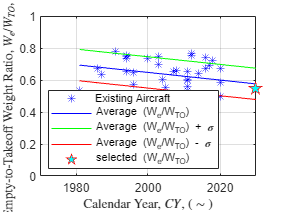


% W_econserv = We2WTOguess_consrv .* W_TOguess;
% W_eaggrsv = We2WTOguess_aggrsv .* W_TOguess;
% fprintf('W_econserv is: %f',W_econserv)
% fprintf('W_eaggrsv is: %f',W_eaggrsv)

% plot the STAMPED analysis
figure;
% plot the raw data
plot(year, W_e2W_TO, 'b*', "DisplayName", "Existing Aircraft")
hold on;

% plot the best fit line
years_plot = [min(year):EIS]; % years to projeect through
plot(years_plot, polyval(p, years_plot), 'b', "DisplayName", "Average (W_e/W_{TO})");
% plot the +- 1 stdev lines
plot(years_plot, polyval(p_plus1std, years_plot), 'g', "DisplayName", "Average (W_e/W_{TO}) + \sigma");
plot(years_plot, polyval(p_min1std, years_plot), 'r', "DisplayName", "Average (W_e/W_{TO}) - \sigma");

% plot the chosen W_e/W_to ratio
plot(EIS, We2WTOguess, "p", 'MarkerFaceColor','cyan', "MarkerEdgeColor","red", 'MarkerSize',10,  "DisplayName", "selected (W_e/W_{TO})")

xlim([1970 EIS])
ylim([0 1])
%title("STAMPED Empty Weight to Take-off Weight Ratio Analysis")
xlabel("Calendar Year, $CY$, ($\sim$)", "Interpreter","latex")
ylabel("Empty-to-Takeoff Weight Ratio, $W_e/W_{TO}$, ($\sim$)", "Interpreter","latex")
legend Location southwest
grid on
hold off